# Lab 5

## Exercise 1

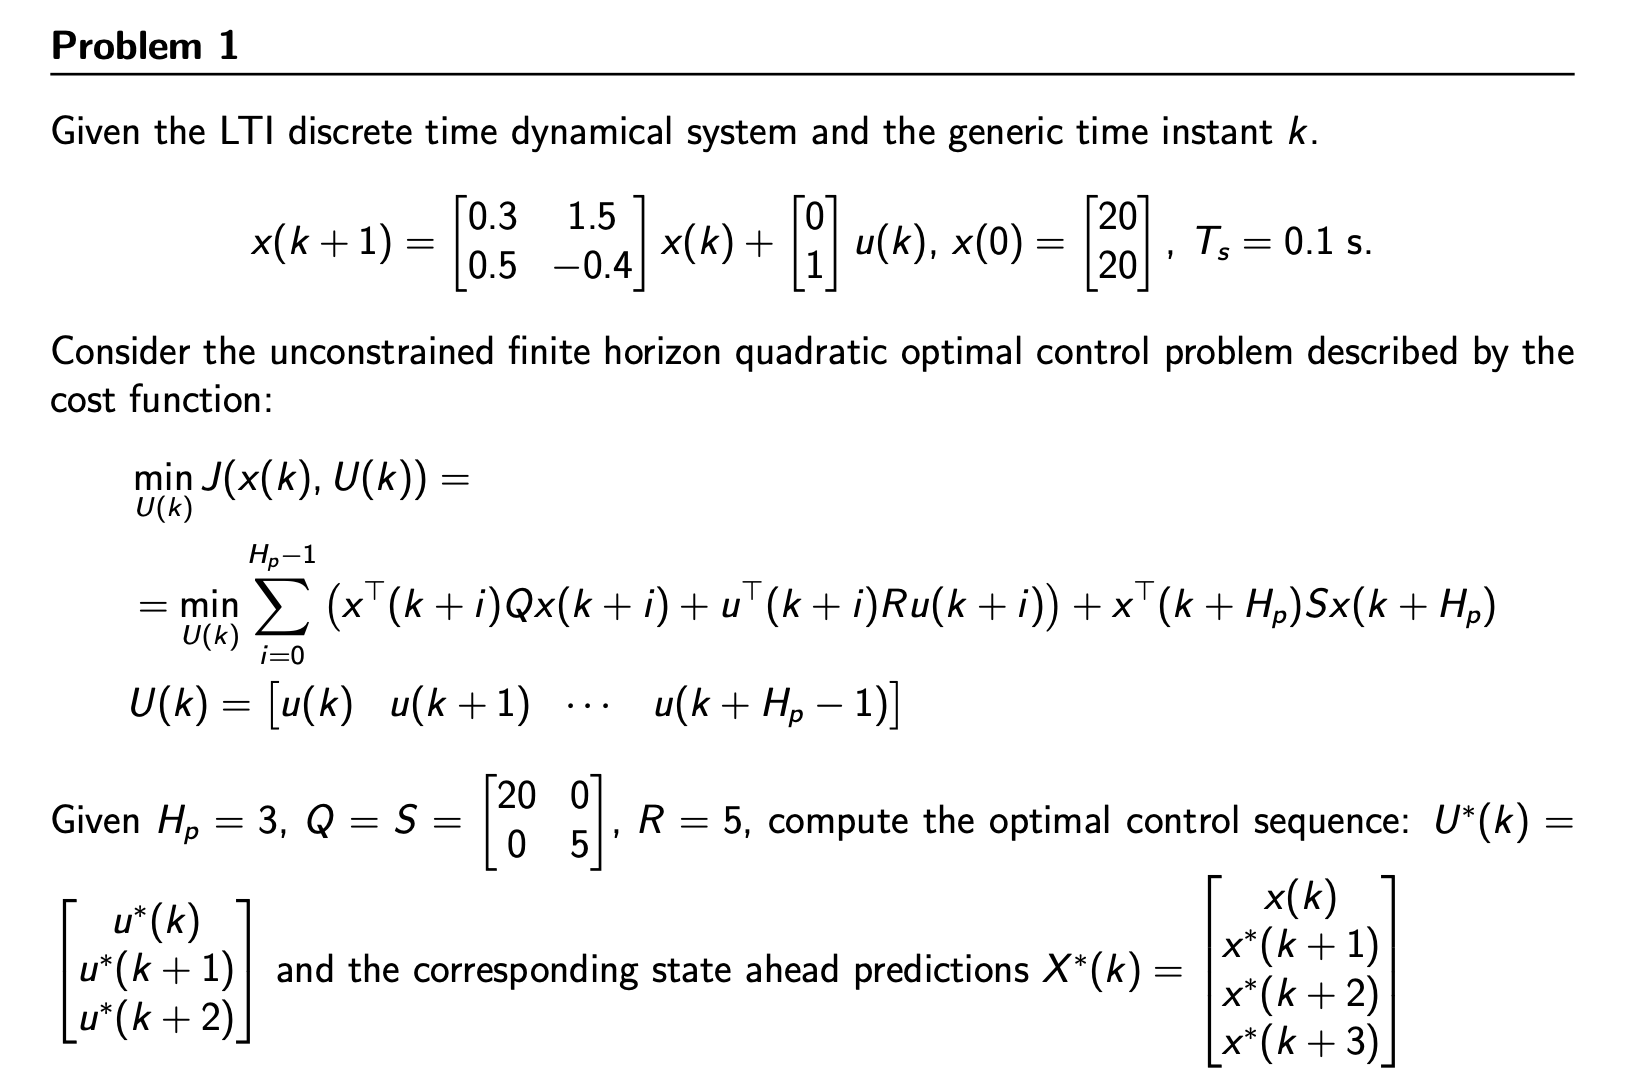

clear
clc
close all
A = [0.3 1.5; 0.5 -0.4];
B = [0;1];
x0 = [20;20];
x_k = x0;
Ts = 0.1;

n = 2; % state dim
p = 1; % input dim

Hp = 3;
Q = [20 0; 0 5];
S = Q;
R = 5;

A_cal = [A;A^2;A^3];
B_cal = [[B zeros(n,1) zeros(n,1)]; [A*B, B, zeros(n,1)]; [A^2*B A*B B]];

Q_cal = blkdiag(Q,Q,Q);
R_cal = blkdiag(R,R,R);

H = 2*(B_cal'*Q_cal*B_cal+R_cal);

F = 2*A_cal'*Q_cal*B_cal

F =    58.5420    8.3600    4.4000
  -28.5549   90.0560   -4.3900



% find input that optimized system
u_k=-H\(F'*x_k)

u_k =    -7.5261
  -18.7716
   -0.3400



X_k=A_cal*x_k+B_cal*u_k

X_k =    36.0000
   -5.5261
    2.5109
    1.4388
    2.9115
    0.3400


## Exercise 2

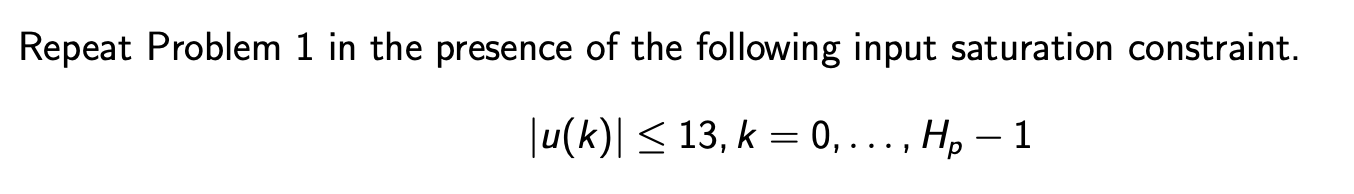

G = [eye(Hp); -eye(Hp)];
u_max = 13;
h = u_max*ones(2*Hp,1); % consider both positive and negative saturation limits

H = (H+H')/2; % we force symmetry 
U = quadprog(H,x_k'*F,G,h)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -6.7928
  -13.0000
    0.4807



% and now find state prediction associated
X_k=A_cal*x_k+B_cal*U

X_k =    36.0000
   -4.7928
    3.6109
    6.9171
   11.4589
   -0.4807


## Exercise 3

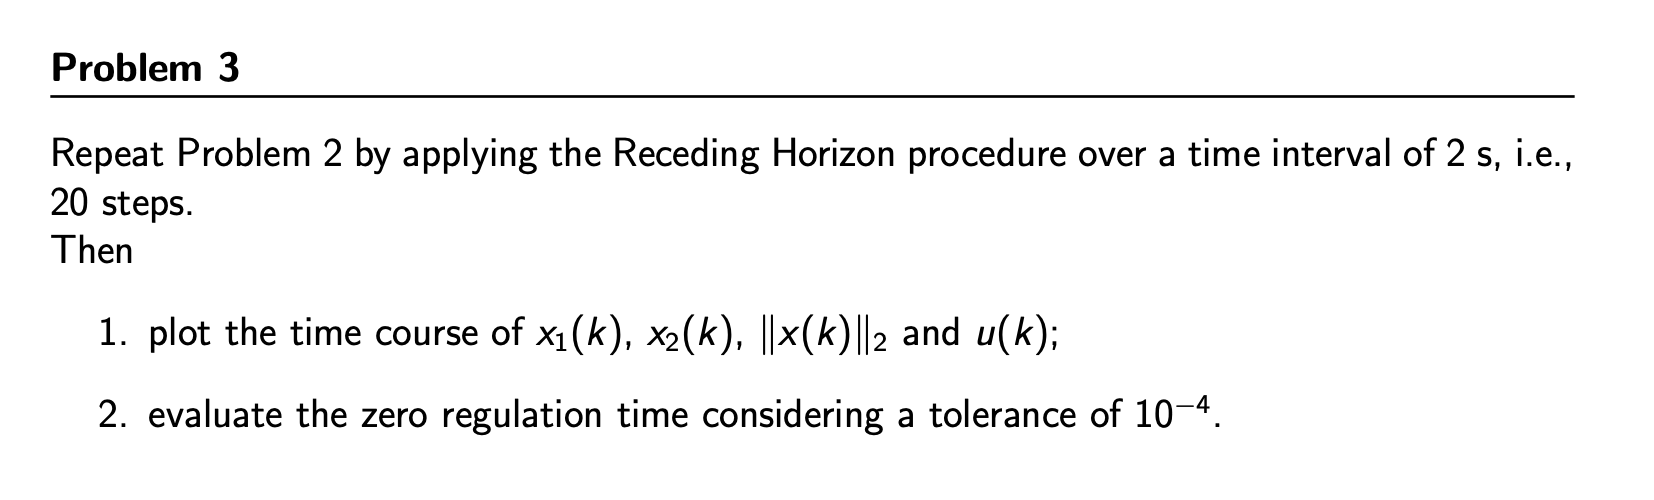

time_interval = 0.5;
steps = time_interval/Ts;

x_traj(:,1) = x_k;

% RH algorithm
for kk=1:steps
    
    % find input that minimize the problem
    U = quadprog(H,x_k'*F,G,h);
    
    % consider just the first input and compute the corresponding state
    x_traj(:,kk+1) = A*x_traj(:,kk) + B*U(1); 
    u_traj(kk) = U(1);

    % update initial state
    x_k = x_traj(:,kk+1);
    
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -6.7928
  -13.0000
    0.4807



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =   -13.0000
   -0.8835
   -3.2337



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.9369
   -5.9937
   -0.0485



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -6.0163
   -0.2324
   -0.2467



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.2371
   -0.4612
   -0.0105


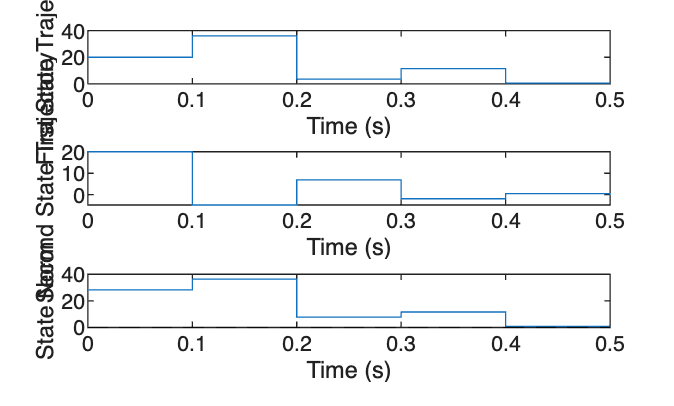


figure
subplot(311)
stairs(0:Ts:steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')
yline(1e-4, 'k--');

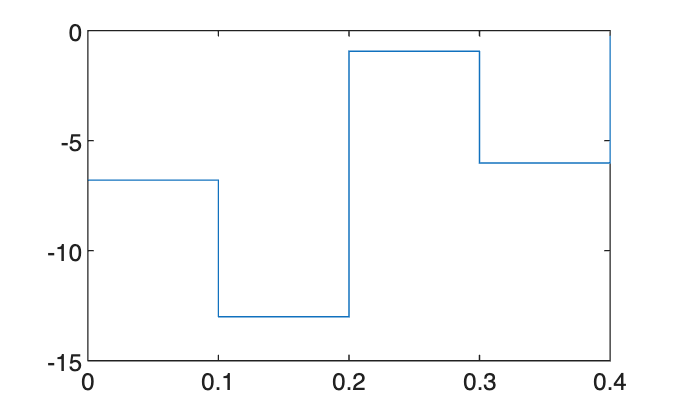


figure(2)
stairs(0:Ts:(steps-1)*Ts, u_traj)

We observed that the state norm will be less then 1e-4 after 1.2s 